clear all
MATRIX = readmatrix("C:\Users\noben\OneDrive - Mälardalens högskola\Documents\GitHub\EXO-Data-Repository\2024_4_6_TestSub21_ARM_L_157");
firstDataBi = MATRIX(5:end-2,2);
firstDataTri = MATRIX(5:end-2,3);

lables = MATRIX(5:end-2,4);
fs1 = 4000;
range = 1000;




j = 1;
for i = 1:100:240000- range
    dataBi = firstDataBi(i:i+range-1);
    Y1 = fft(dataBi);
    fftToPlotBi(:,j) = abs(Y1);
    lableToPrint(j) = lables(i);
    j = j + 1;
end
j = 1;
for i = 1:100:240000- range
    dataTri = firstDataTri(i:i+range-1);
    Y1 = fft(dataTri);
    fftToPlotTri(:,j) = abs(Y1);
    j = j + 1;
end
lablePlot(1:2:1000) = 9000;
lablePlot(2:2:1000) = 0.0001;

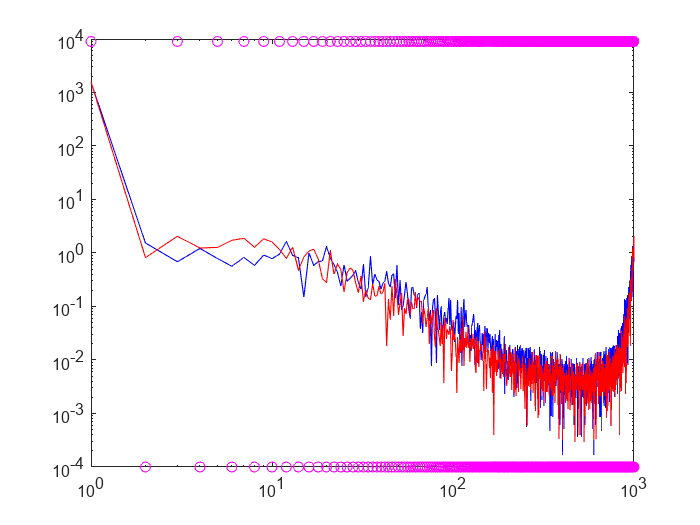



T = length(fftToPlotBi(1,:));
for t = 1:T-1
    
    if(mod(lableToPrint(t),4) == 0)
        loglog(lablePlot,'go')
        hold on
        loglog(fftToPlotBi(:,t),'blue')
        loglog(fftToPlotTri(:,t),'red')
        hold off
    elseif(mod(lableToPrint(t),4) == 1)
        loglog(lablePlot,'co')
        hold on
        loglog(fftToPlotBi(:,t),'blue')
        loglog(fftToPlotTri(:,t),'red')
        hold off
    elseif(mod(lableToPrint(t),4) == 2)
        loglog(lablePlot,'mo')
        hold on
        loglog(fftToPlotBi(:,t),'blue')
        loglog(fftToPlotTri(:,t),'red')
        hold off
    else
        loglog(lablePlot,'yo')
        hold on
        loglog(fftToPlotBi(:,t),'blue')
        loglog(fftToPlotTri(:,t),'red')
        hold off
    end
    xlim([0 1000]);
    ylim([10^-4 10^4])
    pause(5/T)
end